sample_values = double_stunted_gaussian_inverse_gamma(rand(1,1e3),6/10,1/20);
num_values = length(sample_values);
x = 2;

[iterative_profit,win_condition_values,palpha_values,pbeta_values] = iterative_classical_profit_from_sample(sample_values,ones(1,1e3),1,'profit_cutoff',1e-4);
num_iterations = length(unique(palpha_values(~isnan(palpha_values))));

[classical_profit,palpha_final,pbeta_final] = classical_profit_from_sample(sample_values,ones(1,1e3),1,'include_waitbar',0);

[player_struct,mark_1_profit] = mark_1_gambling_system(sample_values,x,'moneyline_tolerance',1);

iterative_profit

iterative_profit = 42.0645

num_iterations

num_iterations = 3

classical_profit

classical_profit = 31.0841

mark_1_profit

mark_1_profit = 33.7950


iterative_focal_outcomes = zeros(1,1e3);
iterative_compliment_outcomes = zeros(1,1e3);

classical_focal_outcomes = zeros(1,1e3);
classical_compliment_outcomes = zeros(1,1e3);

mark_1_focal_outcomes = zeros(1,1e3);
mark_1_compliment_outcomes = zeros(1,1e3);

for index = 1:num_values
    % Iterative
    if ~isnan(win_condition_values(index))
        if win_condition_values(index)
            alpha = 100*palpha_values(index)/(1-palpha_values(index));
            iterative_focal_outcomes(index) = 100/alpha; % Assume bet amount of 1
            iterative_compliment_outcomes(index) = -1;
        else
            beta = 100*pbeta_values(index)/(1-pbeta_values(index));
            iterative_compliment_outcomes(index) = beta/100;
            iterative_focal_outcomes(index) = -1;
        end
    end

    % Classical
    if sample_values(index) >= palpha_final
        alpha = 100*palpha_final/(1-palpha_final);
        classical_focal_outcomes(index) = 100/alpha; % Assume bet amount of 1
        classical_compliment_outcomes(index) = -1; 
    elseif sample_values(index) <= pbeta_final
        beta = 100*pbeta_final/(1-pbeta_final);
        classical_compliment_outcomes(index) = beta/100;
        classical_focal_outcomes(index) = -1;
    end

    % Mark 1
    if player_struct(index).peer2peer_win_condition
        mark_1_focal_outcomes(index) = player_struct(index).pot - player_struct(index).peer2peer_bet_amount;
        mark_1_compliment_outcomes(index) = -player_struct(index).peer2peer_bet_amount;
    else
        mark_1_focal_outcomes(index) = -player_struct(index).peer2peer_bet_amount;
        mark_1_compliment_outcomes(index) = player_struct(index).pot - player_struct(index).peer2peer_bet_amount;
    end

    if ~isnan(player_struct(index).moneyline_win_condition)

        if player_struct(index).moneyline_win_condition
            alpha = 100*player_struct(index).moneyline_palpha/(1-player_struct(index).moneyline_palpha);
            mark_1_focal_outcomes(index) = mark_1_focal_outcomes(index) + 100/alpha*player_struct(index).moneyline_bet_amount;
            mark_1_compliment_outcomes(index) = mark_1_compliment_outcomes(index) - player_struct(index).moneyline_bet_amount;
        else
            beta = 100*player_struct(index).moneyline_pbeta/(1-player_struct(index).moneyline_pbeta);
            mark_1_focal_outcomes(index) = mark_1_focal_outcomes(index) - player_struct(index).moneyline_bet_amount;
            mark_1_compliment_outcomes(index) = mark_1_compliment_outcomes(index) + beta/100*player_struct(index).moneyline_bet_amount;
        end
    end
end

iterative_profit

iterative_profit = 42.0645

sum(iterative_focal_outcomes)

ans = -41.9970

sum(iterative_compliment_outcomes)

ans = -42.0372


classical_profit

classical_profit = 31.0841

sum(classical_focal_outcomes)

ans = -31.0166

sum(classical_compliment_outcomes)

ans = -31.0841


mark_1_profit

mark_1_profit = 33.7950

sum(mark_1_focal_outcomes)

ans = -33.7917

sum(mark_1_compliment_outcomes)

ans = -33.7847

Expected Values

iterative_expected_values = sample_values.*iterative_focal_outcomes + (1-sample_values).*iterative_compliment_outcomes;
iterative_user_value_generated = sum(iterative_expected_values)

iterative_user_value_generated = 27.2607


classical_expected_values = sample_values.*classical_focal_outcomes + (1-sample_values).*classical_compliment_outcomes;
classical_user_value_generated = sum(classical_expected_values)

classical_user_value_generated = 21.9820


mark_1_expected_values = sample_values.*mark_1_focal_outcomes + (1-sample_values).*mark_1_compliment_outcomes;
mark_1_user_value_generated = sum(mark_1_expected_values)

mark_1_user_value_generated = 32.3169

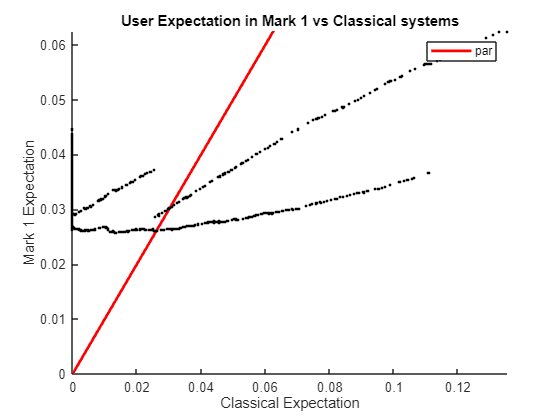


% Mark 1 vs Classical
figure
hold on
plot([0 1],[0 1],'LineWidth',2,'Color',[1 0 0])
plot(classical_expected_values,mark_1_expected_values,'LineStyle','none','Marker','.','Color',[0 0 0])
legend({'par'})
xlabel('Classical Expectation')
ylabel('Mark 1 Expectation')
xlim([0 max(classical_expected_values)])
ylim([0 max(mark_1_expected_values)])
title('User Expectation in Mark 1 vs Classical systems')
hold off

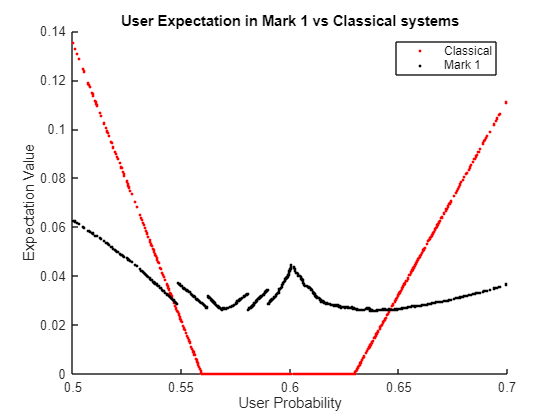


%  Mark 1 vs Classical accross User Probabilities
figure
hold on
plot(sample_values,classical_expected_values,'LineStyle','none','Marker','.','Color',[1 0 0])
plot(sample_values,mark_1_expected_values,'LineStyle','none','Marker','.','Color',[0 0 0])
legend({'Classical','Mark 1'})
xlabel('User Probability')
ylabel('Expectation Value')
title('User Expectation in Mark 1 vs Classical systems')
hold off

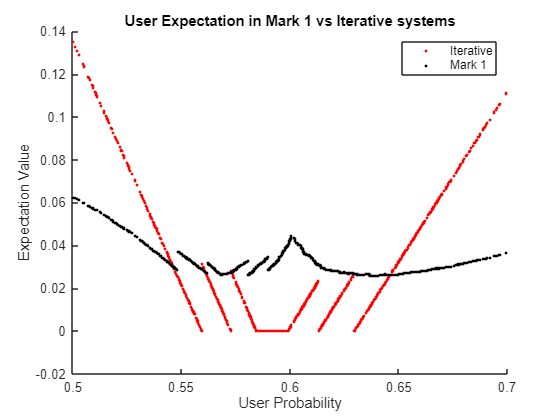


%  Mark 1 vs Iterative accross User Probabilities
figure
hold on
plot(sample_values,iterative_expected_values,'LineStyle','none','Marker','.','Color',[1 0 0])
plot(sample_values,mark_1_expected_values,'LineStyle','none','Marker','.','Color',[0 0 0])
legend({'Iterative','Mark 1'})
xlabel('User Probability')
ylabel('Expectation Value')
title('User Expectation in Mark 1 vs Iterative systems')
hold off